# Unscented Kalman Filter のサンプルコード

p178, カルマンフィルタの基礎，足立修一

例題7.3. 

大気圏外から大気圏に物体が突入するときの状態を推定する．

EKF と　UKFの比較

とりあえず写経

問題設定

% 物理パラメータ値
rho = 1.23;
g = 9.81;
eta = 6e3;
M = 3e4;
a = 3e4;
% 観測条件
T = 0.5; % オイラー法離散化周期
EndTime = 30; % シミュレーション終了時刻
time = 0:T:EndTime;
N = EndTime/T + 1; % データ数
n = 3; % 状態変数の数
R = 4e3; % 観測雑音の分散
Q = 0; % システム雑音はないものとする
B = [0;0;0];

% システム
f = @(x) [x(1)+T*x(2);
    x(2)+T*(0.5*rho*exp(-x(1)/eta)*x(2)^2*x(3)-g);
    x(3)];
h = @(x) sqrt(M^2 + (x(1)-a) .^2);

% f のヤコビアン（EKFで必要）
A = @(x) [1 T 0;
    -0.5*T*rho/eta*exp(-x(1)/eta)*x(2)^2*x(3) ...
    1 + T*rho*exp(-x(1)/eta)*x(2)*x(3) ...
    0.5*T*rho*exp(-x(1)/eta)*x(2)^2;
    0 0 1];

% h のヤコビアン（EKFで必要）
C = @(x) [(x(1)-a)/sqrt(M^2+(x(1)-a)^2); 0; 0];

観測データの生成

w = randn(N, 1)*sqrtm(R); % 観測雑音
x = zeros(N, n); y = zeros(n, 1); % 記憶領域の確保
% 初期状態
x(1, :) = [90000; -6000; 0.003]';
y(1) = h(x(1, :)) + w(1);

% 時間更新
for k = 2:N
    x(k, :) = f(x(k-1, :));
    y(k) = h(x(k, :)) + w(k);
end

EKFアルゴリズム

x_hat_ekf = zeros(N, 3); % 推定値記憶領域の確保
% 初期値の設定
xhat_ekf(1, :) = x(1, :); % 状態推定値
P_ekf = [9e3 0 0; 0 4e5 0; 0 0 0.4]; % 誤差共分散

% 推定値を反復更新
for k = 2:N
    [xhat_ekf(k, :), P_ekf] = ...
        ekf(f, h, A, B, C, Q, R, y(k), xhat_ekf(k-1, :), P_ekf);
end

UKFアルゴリズム

x_hat_ukf = zeros(N, 3);
% 初期値
xhat_ukf(1, :) = x(1, :); % 状態推定値
P_ukf = [9e3 0 0; 0 4e5 0; 0 0 0.4]; % 誤差共分散
% 推定値を反復更新
for k = 2:N
    [xhat_ukf(k, :), P_ukf, G] = ...
        ukf(f, h, B, Q, R, y(k), xhat_ukf(k-1, :), P_ukf);
end

結果の表示

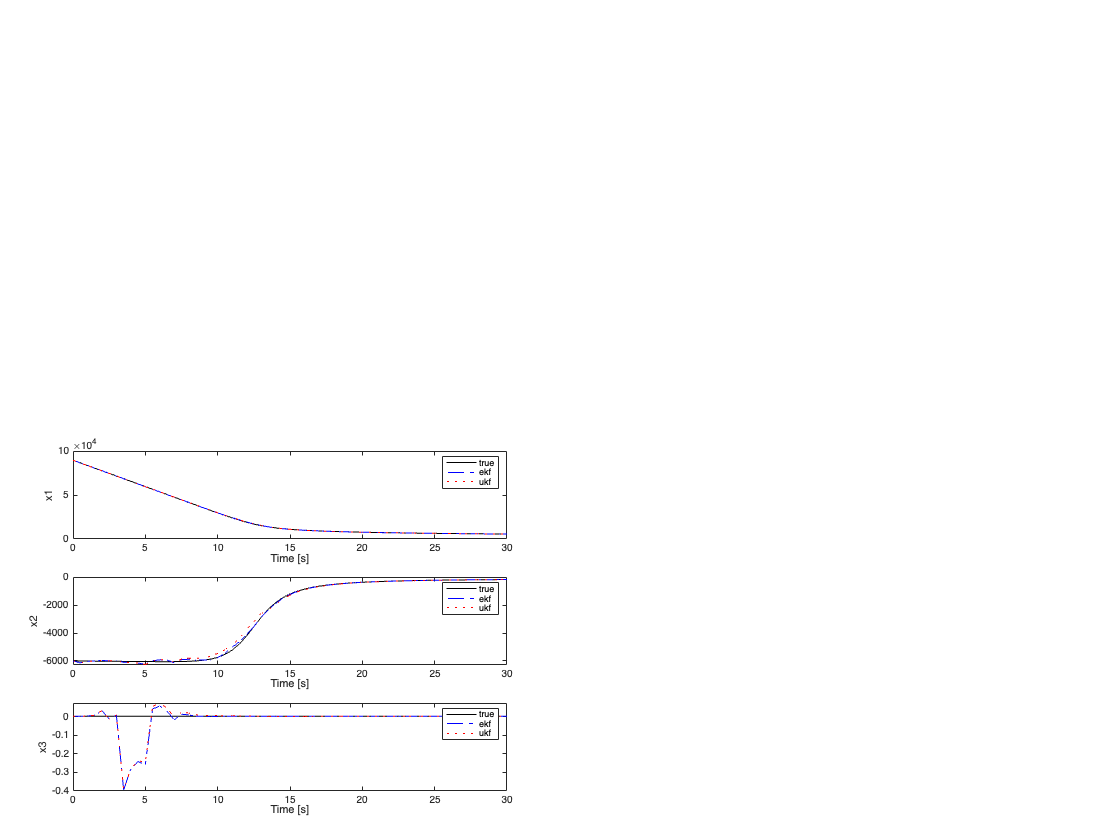

% 状態の真値の図示
figure(2), clf
for p = 1:3
    subplot(3, 1, p)
    plot(time, x(:, p), 'k', ...
        time, xhat_ekf(:, p), 'b-.', ...
        time, xhat_ukf(:, p), 'r:');
    xlabel('Time [s]'), ylabel(sprintf('x%d', p))
    legend('true', 'ekf', 'ukf')
end


% RMSEの表示
RMSE = @(x) sqrt(mean(x.^2));
fprintf('%10s %10s %10s\n', 'variable', 'RMSE(ekf)', 'RMSE(ukf)');

  variable  RMSE(ekf)  RMSE(ukf)


for p = 1:3
    vname = sprintf('x%d', p);
    fprintf('%10s % 10.5f % 10.5f\n', ...
        vname, RMSE(xhat_ekf(:, p) - x(:, p)), ...
        RMSE(xhat_ukf(:, p) - x(:, p))); % なんで% 10.5fでスペースが空いてんの
end

        x1   79.31635  110.45801
        x2   66.10568  148.35383
        x3    0.07872    0.07824


### UKF

function [xhat_new, P_new, G] = ukf(f, h, B, Q, R, y, xhat, P)

UKF の更新式

[xhat_new, P_new, G] = ukf(f, h, B, Q, R, y, xhat, P)

UKFの推定値更新を行う

引数：

    f, h, B: 対象システム

        x(k+1) = f(x(k)) + Bv(k)

        y(k) = h(x(k)) + w(k)

        を記述する関数への関数ハンドルf, h および行列 B

    注意：対象システムが既知の制御入力 u を持つ関数 fu(x(k), u(k))

        で記述される場合．

            f=@(x) fu(x, u(k))

        を与えれば良い．

    Q, R: 雑音v, wの共分散行列．v, wは正規性白色雑音で

            E[v(k)] = E[w(k)] = 0

            E[v(k)'v(k)] = Q, E[w(k)'w(k)] = R

        であることを想定

    y: 状態更新後時点での観測出力 y(k)

    xhat, P: 更新前の状態推定値 xhat(k-1)・誤差共分散行列 P(k-1)

戻り値：

    xhat_new: 更新後の状態推定値 xhat(k)

    P_new: 更新後の誤差共分散行列 P(k)

    G: カルマンゲイン G(k)

% 列ベクトルに整形
xhat = xhat(:);
y = y(:);
% 事前推定値
[xhatm, Pm, ~] = ut(f, xhat, P); % U変換による遷移後状態の近似
Pm = Pm + B*Q*B'; % システム雑音を考慮
[yhatm, Pyy, Pxy] = ut(h, xhatm, Pm); % U変換による出力値の近似
% カルマンゲイン行列
G = Pxy / (Pyy+R);
% 事後推定値
xhat_new = xhatm + G*(y-yhatm); % 状態
P_new = Pm - G*Pxy'; % 誤差共分散
end

UTのfunction 文（U Transform）

function [ym, Pyy, Pxy] = ut(f, xm, Pxx)
% 準備 -----
% 列ベクトルに整形
xm = xm(:);
% mapcols(f, x): xの各列をfで写像する関数
mapcols = @(f, x) ...
    cell2mat( ...
        cellfun(f, ...
            mat2cell(x, size(x, 1), ones(1, size(x,2))) ...
                , 'UniformOutput', false));
% 定数
n = length(xm); % 次数
kappa = 3 - n; % スケーリングパラメータ
w0 = kappa / (n+kappa);
wi = 1/(2*(n+kappa));
W = diag([w0; wi*ones(2*n, 1)]);

% U変換 -----
% シグマポイントの生成
L = chol(Pxx);
X = [xm';
    ones(n, 1)*xm' + sqrt(n+kappa)*L;
    ones(n, 1)*xm' - sqrt(n+kappa)*L];
% シグマポイントに対応する y を計算
Y = mapcols(f, X')';
% y の期待値
ym = sum(W*Y)';
% 共分散行列
Yd = bsxfun(@minus, Y, ym'); % 平均値の除去
Xd = bsxfun(@minus, X, xm'); % 平均値の除去
Pyy = Yd'*W*Yd;
Pxy = Xd'*W*Yd;
end


### EKF

function [xhat_new, P_new, G] = ekf(f, h, A, B, C, Q, R, y, xhat, P)

EKF拡張カルマンフィルタの更新式

[xhat_new, P_new, G] = ekf(f, h, A, B, C, Q, R, y, xhat, P)

線形カルマンフィルタの推定値更新を行う

引数：

    f, h, B: 対象システム

        x(k+1) = f(x(k)) + Bv(k)

        y(k) = h(x(k)) + w(k)

        を記述する関数への関数ハンドル f, h および行列 B

    注意：対象システムが既知の制御入力 u を持つ関数 fu(x(k), u(k))

    で記述される場合

    f = @(x) fu(x, u(k))

    を与えれば良い．

A, C: f, hのヤコビアンを’計算する関数への関数ハンドル

Q, R: 雑音v, w の共分散行列．v, wは正規性白色雑音で

    E[v(k)] = E[w(k)] = 0

    E[v(k)' v(k)] = Q, E[w(k)' w(k) = R

    であることを想定

y: 状態更新後時点での観測出力 y(k)

xhat, P: 更新前の状態推定値 xhat(k-1) (行ベクトル) ,  誤差共分散行列 P(k-1)  

戻り値：

    xhat_new: 更新後の状態推定値 xhat(k)

    P_new: 更新後の誤差共分散行列 P(k)

    G: カルマンゲイン G(k)

参考：

    線形カルマンフィルタ: KF

    Unscented カルマンフィルタ： UKF

% 列ベクトルに整形
xhat = xhat(:);
y = y(:);
% 事前推定値
xhatm = f(xhat); % 状態
Pm = A(xhat)*P*A(xhat)' + B*Q*B'; % 誤差共分散
% カルマンゲイン
G = Pm*C(xhatm)/(C(xhatm)'*Pm*C(xhatm)+R);
% 事後推定値
xhat_new = xhatm + G*(y-h(xhatm)); % 状態
P_new = (eye(size(A(xhat))) - G*C(xhatm)') * Pm; % 誤差共分散
end